# Datasets y Visualización

### Importar con readtable y readmix

%readmatrix
area_mm=readmatrix("../../../Utils4SP/Datasets/areaMM.txt","Delimiter","   ")

area_mm =   340.4277  324.3750  308.9114  293.6813  277.8073  261.0772  245.9019  232.8705  218.6999  203.1390  189.3382  176.6128  169.5532  168.8775  172.0049  174.4247  178.4295  183.9891  193.8382  206.2434  219.7135  234.3422  248.6808  263.1539  276.9246  293.0711  308.6514  324.5290  339.1647  348.7149  354.1932  356.6855  356.3495  354.7398  355.8347  358.5429  363.1208  370.1026  377.4434  387.1900  396.7827  403.9608  411.5069  420.4716  429.3214  439.3651  448.8747  459.0157  469.0630  478.9387


%readtable
PSD_bands=readtable("../../../Utils4SP/Datasets/2021.10.04_IntensidadBobinas.xlsx")

PSD_bands = 630×13 table
    Dist_cm_    PSD_B1      PSD_B2        PSD_B3       PSD_B4       PSD_B5      PSD_B6      PSD_B7       PSD_B8       PSD_B9       PSD_B10      PSD_B11     PSD_Base 
    ________    _______    _________    __________    _________    _________    _______    _________    _________    _________    _________    _________    _________

      0.5       0.54799     0.012948     0.0051533    0.0046358     0.020502     1.1388     0.010652    0.0029874    0.0060306    0.0044177    0.0027482     0.008748
      0.5       0.50418    0.00171

### Funcion custom de Import File

%Sonda Cassini
%Cassini=importfile_cassini("../../../Utils4SP/Datasets/05358_mrdcd_sdfgmc_krtp_1s.asc,88,200);

### Importar audio

[y,fs]=audioread("../../../Utils4SP/Datasets/Owl.wav");
%Para escuchar el audio:
sound(y,fs);

### Datastore

%Le indicamos que la carpeta es una datastore
ds=datastore("../../../Utils4SP/Datasets/AtmosferaLogger/");
ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"]

ds =   TabularTextDatastore with properties:

                      Files: {
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210425.txt';
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210426.TXT';
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210427.TXT'
                              ... and 35 more
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: false
              VariableNames: {'Fecha', 'Hora', 'Pres_kpa' ... and 2 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: {' ', '\t'}
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f'

ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f"]

ds =   TabularTextDatastore with properties:

                      Files: {
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210425.txt';
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210426.TXT';
                             'C:\Users\HD\Utils4SP\Datasets\AtmosferaLogger\210427.TXT'
                              ... and 35 more
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: false
              VariableNames: {'Fecha', 'Hora', 'Pres_kpa' ... and 2 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: {' ', '\t'}
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%s'

%ds.Delimiter="";
%ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"]
%ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f" "%f"]

%Leer todas las entradas
atmosfera=readall(ds)

atmosfera = 546110×5 table
     Fecha         Hora       Pres_kpa    Temp_C    Hum_perc
    ________    __________    ________    ______    ________

    '210425'    '21:03:51'     78.05      28.79      33.52  
    '210425'    '21:03:56'     78.05      29.12      33.12  
    '210425'    '21:04:01'     78.05      29.16      33.09  
    '210425'    '21:04:06'     78.05       29.2      36.58  
    '210425'    '21:04:11'     78.05       29.3      35.68  
    '210425'    '21:04:16'     78.05      29.37      34.48  
    '210425'    '21:04:22'     78.05      29.43      33.99  
    '210425'    '21:04:27'     78.05       29.5         34  
    '210425'    '21:04:32'     78.05      29.57      34.21  
    '210425'    '21:04:37'     78.05      29.63      33.81  
    '210425'    '21:04:42'     78.05      29.69      34.01  
    '2104

### Reordenando

%Solo si importa fecha y hora en dos columnas
atmosfera.DateTime=string(atmosfera.Fecha)+" "+string(atmosfera.Hora);
%Pasar de texto a fecha-hora
atmosfera.DateTime=datetime(atmosfera.DateTime,"Format","yyyyMMdd HH:mm:ss");


### Reordenado

Tomaremos datos de entre el 18-May y el 26 de mayo a las 6am

%Puntos inicial y final en el tiempo
T1=datetime(2021,5,18,6,0,0)

T1 = datetime
   18-May-2021 06:00:00


T2=datetime(2021,5,26,6,0,0)

T2 = datetime
   26-May-2021 06:00:00



%Creando criterios de selección de datos
index=atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;

### Ploteo

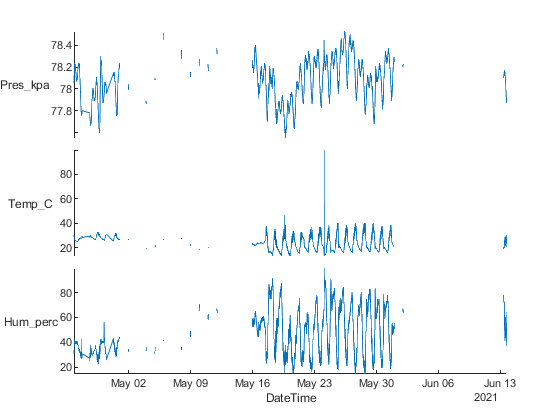

ans =   StackedLineChart with properties:

         SourceTable: [546110×6 table]
    DisplayVariables: {'Pres_kpa'  'Temp_C'  'Hum_perc'}
           XVariable: 'DateTime'
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


figure
stackedplot(atmosfera,"XVariable","DateTime")

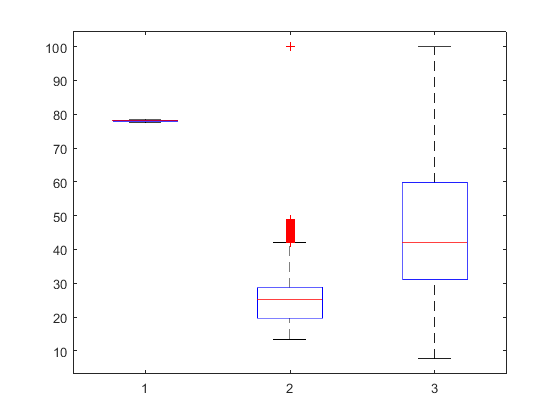


figure
boxplot(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

### Histograma

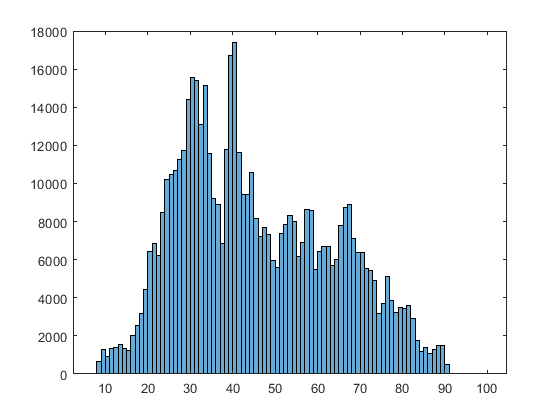

figure
histogram(atmosfera.Hum_perc,"BinWidth",1)

### Plot matrix

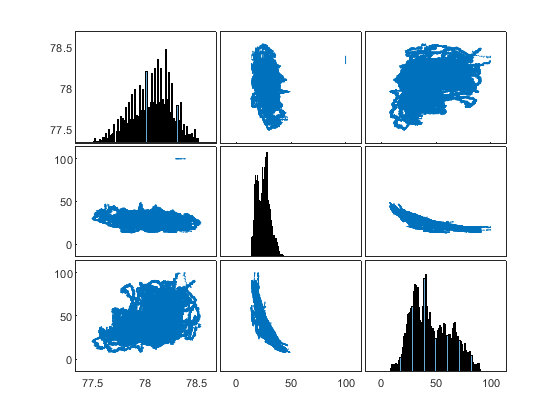

figure
plotmatrix(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

### Tiledlayout

% %tiledlayout("flow")
% tiledlayout(3,1)
% nexttile
% plot(atmosfera_part.DateTime,atmosfera_part.Pres_kpa)
% ylabel("Presión [kpa] \sigma")
% %xlabel("Fecha")
% title("Parámetros atmosféricos en mi casa")
% set(gca,"xtick",[])
% 
% nexttile
% plot(atmosfera_part.DateTime,atmosfera_part.Temp_C)
% ylabel("Temperatura [°C] \sigma")
% %xlabel("Fecha ")
% set(gca,"xtick",[])
% 
% nexttile
% plot(atmosfera_part.DateTime,atmosfera_part.Hum_perc)
% ylabel("Humedad [°] \sigma")
% %xlabel("Fecha ")
% set(gca,"xtick",[])


### Agrupación y orden

%Darle categorías a temperatura
%Fronteras de las categorías
edges=[-30 10 20 55]

edges =    -30    10    20    55



%Categorías
categorias=["Frío" "Templado" "Caliente"]

categorias = 1×3 string array
    "Frío"    "Templado"    "Caliente"


%Clasifico las temp con un categorico
temp_cats=discretize(atmosfera_noNaNs.Temp_C,edges,'categorical',categorias)

Undefined variable "atmosfera_noNaNs" or class "atmosfera_noNaNs.Temp_C".

%Lo agrego a la tabla original
atmosfera_noNaNs.temp_cats=temp_cats
%Ordenamiento
temp_Descend=sort(atmosfera_noNaNs.Temp_C,'descend')
temp_Ascend=sort(atmosfera_noNaNs.Temp_C,'ascend')

figure
plot([temp_Ascend temp_Descend])
ylabel("Temperatura [°C]")
xlabel("Número de muestra")
legend("Ascendente","Descendente")
title("Ordenamiento de temperatura atmosférica")